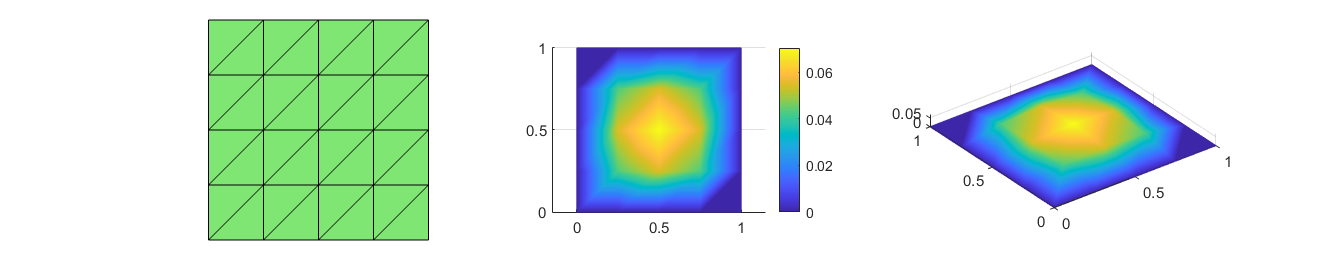

clear all
node = [0,0; 1,0; 1,1; 0,1];
elem = [2,3,1; 4,1,3];      
for k = 1:2
  [node,elem] = uniformrefine(node,elem);
end
% Homogenous Dirichlet boundary condition
pde.f = inline('ones(size(p,1),1)','p');
pde.g_D = 0;
u = Poisson(node,elem,[],pde);
figure(1); 
showresult(node,elem,u);

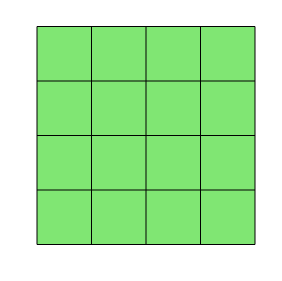

ans =   Patch with properties:

    FaceColor: [0.5000 0.9000 0.4500]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [16×4 double]
     Vertices: [25×2 double]

  Show all properties


clear all
node=  [0, 0; 1, 0; 1, 1; 0,1];
elem = [1,2,3,4];
for k = 1:2
    [node,elem] = uniformrefinequad(node,elem);
end
figure('rend','painters','pos',[10 10 225 225]);
showmesh(node,elem)

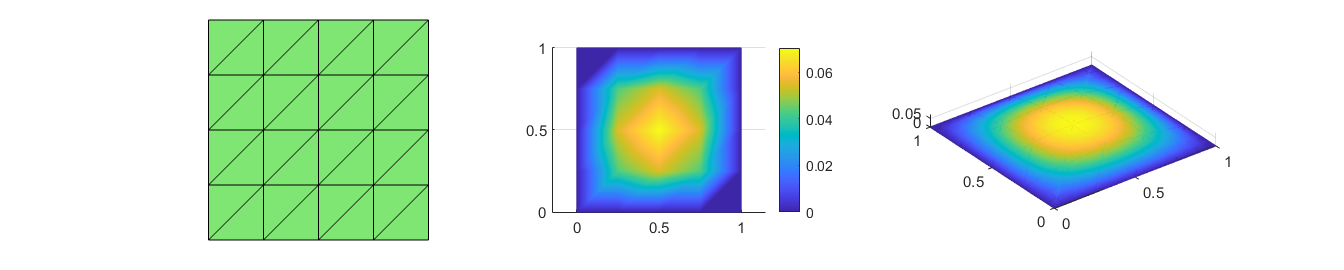


% Homogenous Dirichlet boundary condition
pde.f = inline('ones(size(p,1),1)','p');
pde.g_D = 0;
u = PoissonQ1(node,elem,[],pde);
figure(1); 
showsolution(node,elem,u);

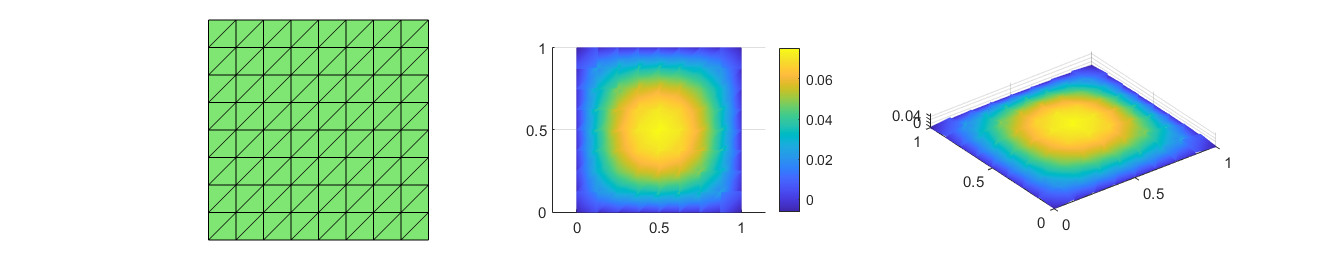

clear all
node = [0,0; 1,0; 1,1; 0,1];
elem = [2,3,1; 4,1,3];      
for k = 1:3
  [node,elem] = uniformrefine(node,elem);
end
% Homogenous Dirichlet boundary condition
pde.f = inline('ones(size(p,1),1)','p');
pde.g_D = 0;
u = PoissonCR(node,elem,[],pde);
figure(1); 
showresult(node,elem,u);